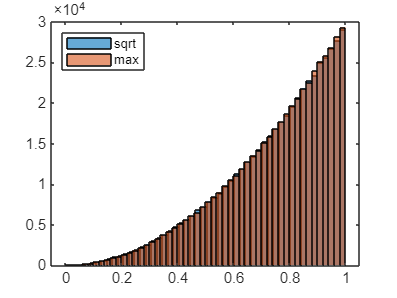

% Leo Beck
% rand(x)^2 = max(rand(x), rand(x))
% 2026-06-22

% Showing that the distribution for sqrt(rand(x)) is equal
% to distribution of the max of 2 random numbers
clear
clc

rng(0,"twister")    % choose rng method
n_samp = 500000;    % # samples
n_bins = 50;        % # hist bins
m = 3;              % integer - dims
a = 1;              % lower bound - must be 0
b = 0;              % upper bound - must be 1

% sqrt(rand(x))
xs = (b-a)* rand(n_samp,1) + a;
xss = xs.^(1/m);

% max(rand(x1), rand(x2))
ys = (b-a)* rand(n_samp,m) + a;
ysm = max(ys, [], 2);

% Plot distributions
histogram(xss, n_bins)
hold on
histogram(ysm, n_bins)
legend('sqrt', 'max', 'Location','northwest')